# Definir un sistema tipo "transfer function"

Declaro a "s" como una variable de tipo "transfer function" usando la función **tf**:

s = tf('s'); 

Defino mi sistema en terminos de Laplace:

G = (s + 3)/((s + 1)*(s + 2)); 

# Hallar la rta de un sistema

#### Función step:

Usando **step** se halla la respuesta de G ante una entrada escalón unitario:

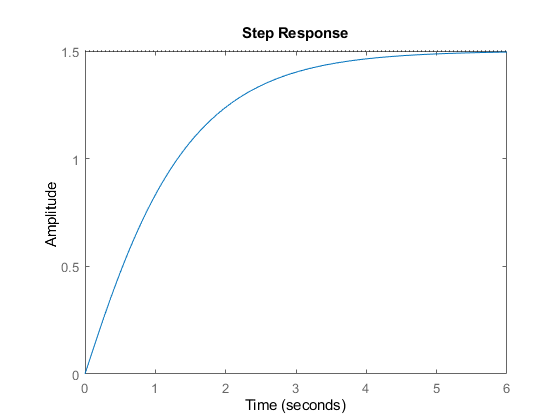

step(G) 

Se puede definir el tiempo que se desea que dure la respuesta y otras opciones adicionales, usar el comando ***help*** para más información.

#### Función lsim:

Defino el vector de tiempo que deseo para mi simulación

t = 0:0.01:10;

defino un vector de entrada que debe depender del vector de tiempo **t**. Recomiendo usar la función **heaviside **que representa halla un escalon para el vector que se le asigne como parámetro (es como hacer **u(t)** en señales, y se puede usar de la misma forma, es decir, si se pone **heaviside(t - 1)** será igual a **u(t - 1)**, un desplazamiento, pueden probar rampa haciendo **tu(t)**, como en señales).

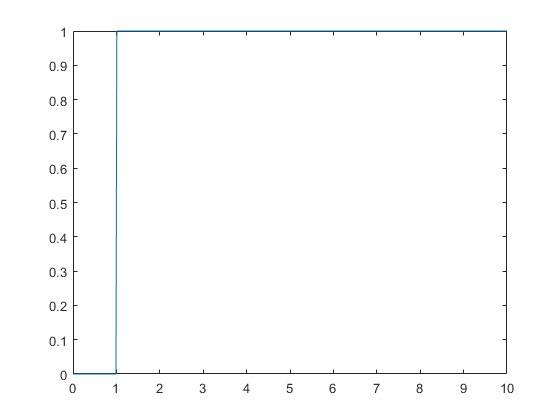

u = heaviside(t-1);
plot(t,u)

Usando **lsim** se halla la respuesta de G ante una entrada **u**, en un tiempo **t**:

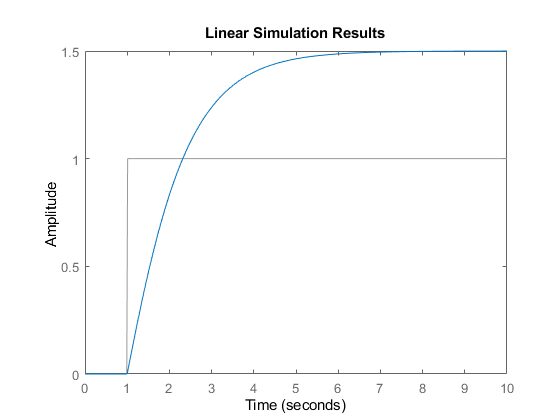

lsim(G,u,t)

Si se desea usar **plot**, ya sea con los resultados de **step** o los de **lsim**, se puede almacenar su respuesta en un vector **y**.

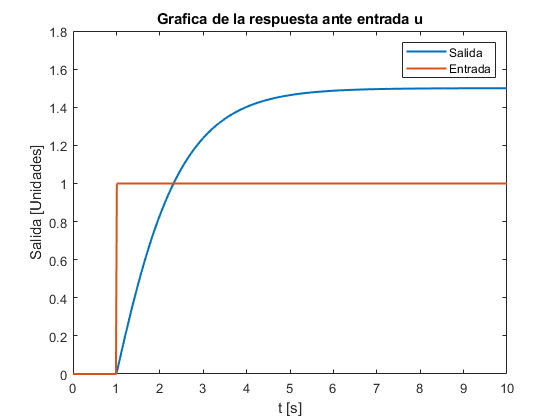

y = lsim(G,u,t);
plot(t,y,t,u,'LineWidth',1.5)
title('Grafica de la respuesta ante entrada u')
ylabel('Salida [Unidades]'), xlabel('t [s]')
legend('Salida','Entrada'), ylim([0 1.8])

Pueden usar **plot**, **subplot**, **legend**, **xlabel**, etc. para que las graficas se vean mejor.

# Lazo cerrado

#### Función feedback:

De existir, defino H en terminos de Laplace:

H = 1; 

Cierro el lazo usando la función **feedback, **donde **G** es lo que tiene el **lazo directo** y **H** lo que tiene **el lazo de realimentación**, ojo **NO** el **lazo abierto**:

C = feedback(G,H);

Cualquier inquietud mirar la documentación de feedback usando **help**.